# `实验 交通标志的定位`

clear
close all
clc

## `1. 图像预处理`

### `1.1 读取图片`

% 读取图片    
img = imread("../imgs/test_imgs/00569.jpg");

### 1.2 中值滤波

% 提取图像的各个通道
r_channel = img(:, :, 1);
g_channel = img(:, :, 2);
b_channel = img(:, :, 3);

% 对每个通道进行中值滤波
r_channel = medfilt2(r_channel);
g_channel = medfilt2(g_channel);
b_channel = medfilt2(b_channel);

### 1.3 直方图均衡化

% 对每个通道进行直方图均衡化
r_enhanced = imadjust(r_channel, stretchlim(r_channel), []);
g_enhanced = imadjust(g_channel, stretchlim(g_channel), []);
b_enhanced = imadjust(b_channel, stretchlim(b_channel), []);

### 1.4 阶段结果

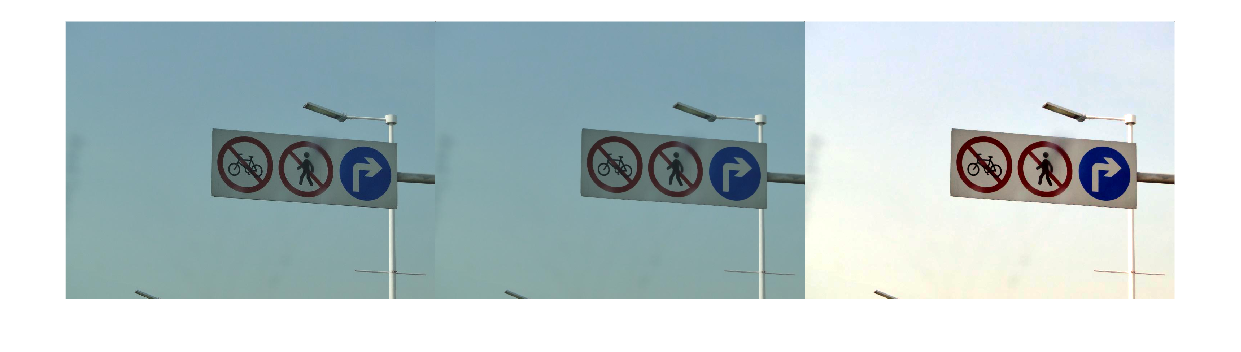

figure
imshow([img cat(3, r_channel, g_channel, b_channel) cat(3, r_enhanced, g_enhanced, b_enhanced)])

## 2. 颜色阈值分割

% 红蓝（参考论文）
con1 = max(0, max((b_enhanced - g_enhanced - r_enhanced), (r_enhanced - b_enhanced - g_enhanced)));

% 黄（网上找的经验法）
con2 = (img(:,:,1) > 160 & img(:,:,2) > 90 & img(:,:,3) < 90 ...
    & abs(double(img(:,:,1)) - double(img(:,:,2))) < 100 & abs(double(img(:,:,1)) - double(img(:,:,3))) > 90);

% 按权重合并合并两个结果
segment_result = 0.6 * mat2gray(con1) + 0.4 * double(con2);

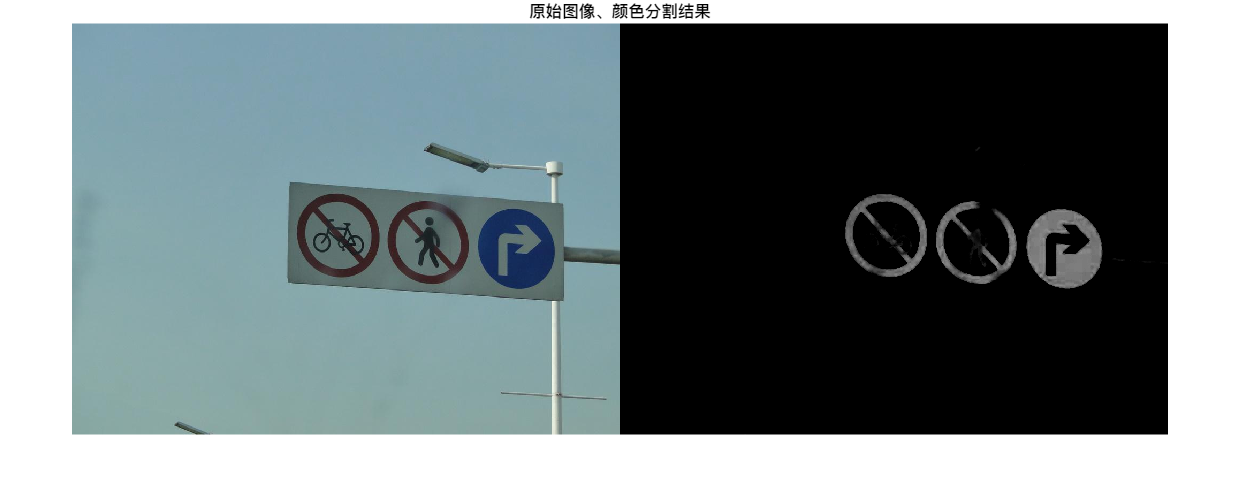

% 可视化合并后的结果
figure;
imshow([img, ...
    255*cat(3, segment_result, segment_result, segment_result)]);
title('原始图像、颜色分割结果');

## 3. 二值化

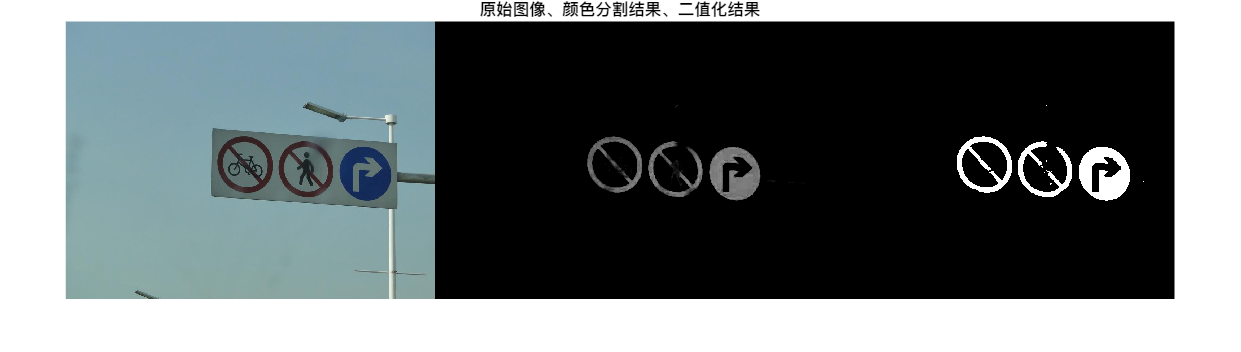

% 经验阈值化
threshold = 0.1;
binary_result = segment_result > threshold;

% 可视化合并后的结果
figure;
imshow([img, ...
    255*cat(3, segment_result, segment_result, segment_result), ...
    255*cat(3, binary_result, binary_result, binary_result)]);
title('原始图像、颜色分割结果、二值化结果')

## 4. 形态学处理

### 4.1 闭操作

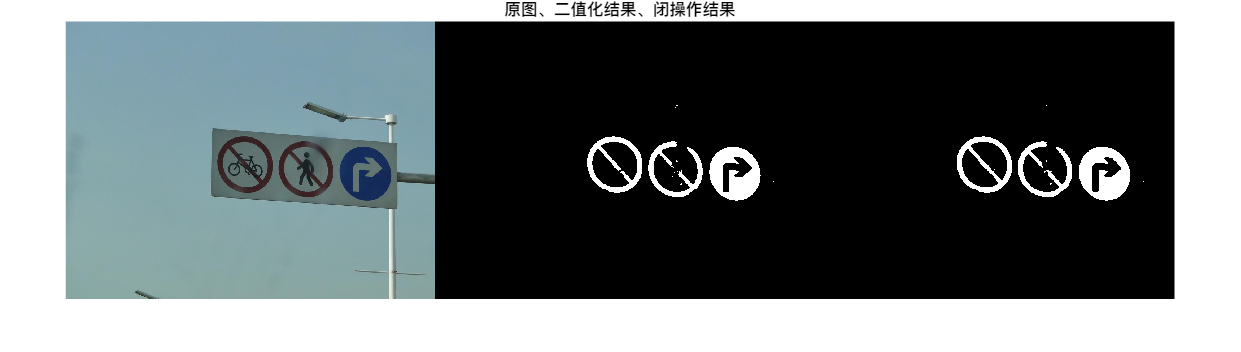

% 形态学闭运算
se = strel('disk', 4);
binary_close = imclose(binary_result, se);


figure
imshow([img, ...
    255*cat(3, binary_result, binary_result, binary_result), ...
    255*cat(3, binary_close, binary_close, binary_close)]);
title('原图、二值化结果、闭操作结果');

### 4.2 去除孤立小区域

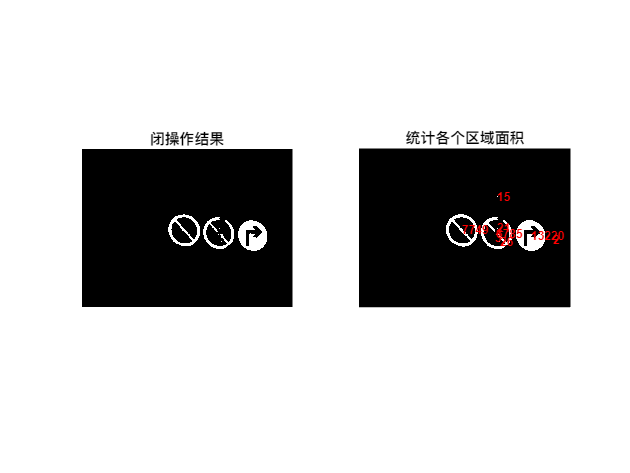

% 统计各个区域的面积
stats = regionprops(binary_close, 'Area', 'Centroid');

figure
subplot(1,2,1)
imshow(binary_close)
title('闭操作结果');
subplot(1,2,2)
imshow(binary_close);
title('统计各个区域面积');
hold on;

% 在图像上标记每个区域的面积
for k = 1:length(stats)
    area = stats(k).Area;
    centroid = stats(k).Centroid;
    text(centroid(1), centroid(2), sprintf('%d', area), ...
        'Color', 'red', 'FontSize', 8, 'FontWeight', 'bold');
end
hold off;

% 去除小区域
% binary_cleaned = bwareaopen(binary_close, 500);% 更加干净，但误伤小目标
binary_cleaned = bwareaopen(binary_close, 85);% 为了保留小目标

### 4.3 阶段处理结果

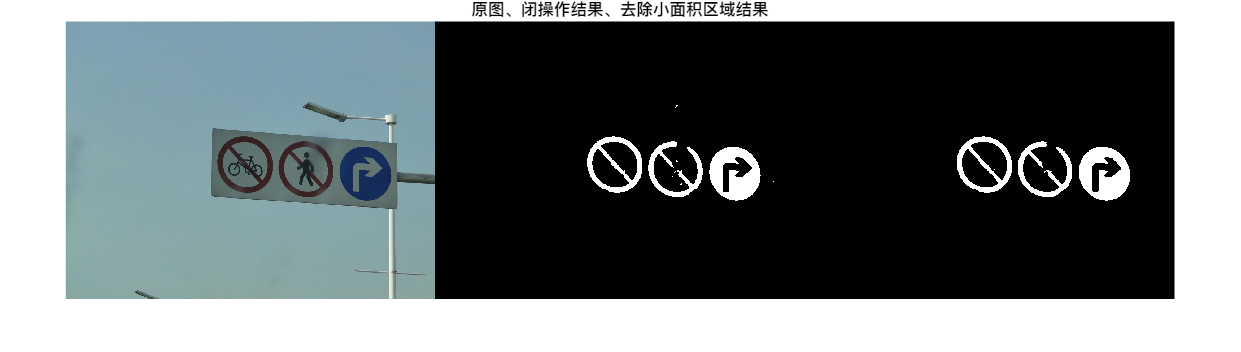

figure
imshow([img, ...
    255*cat(3, binary_close, binary_close, binary_close), ...
    255*cat(3, binary_cleaned, binary_cleaned, binary_cleaned)]);

title('原图、闭操作结果、去除小面积区域结果');

## 5. MSER区域检测

### 5.1 检测MSER区域&测量区域属性

% 检测MSER（Maximally Stable Extremal Regions）区域
[~, mserConnComp] = detectMSERFeatures(binary_cleaned, ...
    'RegionAreaRange', [30 30000], ...
    'ThresholdDelta', 5.5);

% 使用 regionprops 测量 MSER 区域的属性
mserStats = regionprops(mserConnComp, 'BoundingBox', 'Area','Eccentricity', ...
    'Solidity', 'Extent', 'Euler', 'Image');

### 5.2 提取所有MSER区域边界框&绘制

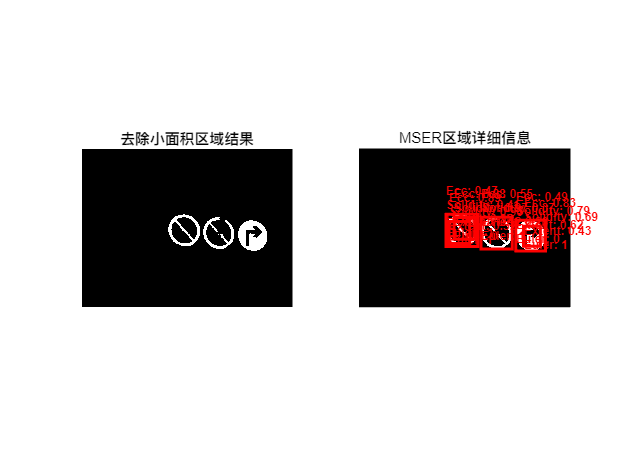

% 提取所有MSER区域的边界框
bboxes = vertcat(mserStats.BoundingBox);

% 显示原始图像
figure;
subplot(1,2,1)
imshow(binary_cleaned);
title('去除小面积区域结果');

% 计算每个区域的偏心率、固实度、面积比、欧拉数
eccentricity = [mserStats.Eccentricity];
solidity = [mserStats.Solidity];
extent = [mserStats.Extent];
eulerNumber = [mserStats.EulerNumber];

% 创建图像
subplot(1,2,2)
imshow(binary_cleaned);
hold on;

for k = 1:length(mserStats)
    % 获取当前区域的边界框和属性
    bbox = bboxes(k, :);
    ecc = eccentricity(k);
    sol = solidity(k);
    ext = extent(k);
    euler = eulerNumber(k);

    % 在图像上绘制当前区域的边界框
    rectangle('Position', bbox, 'EdgeColor', 'r', 'LineWidth', 2);

    % 标注当前区域的属性信息
    text(bbox(1), bbox(2) - 10, sprintf('Ecc: %.2f\nSolidity: %.2f\nExtent: %.2f\nEuler: %d', ecc, sol, ext, euler), ...
        'Color', 'r', 'FontSize', 8, 'FontWeight', 'bold');
end

hold off;
title('MSER区域详细信息');

### 5.3 对每个MSER区域进行膨胀

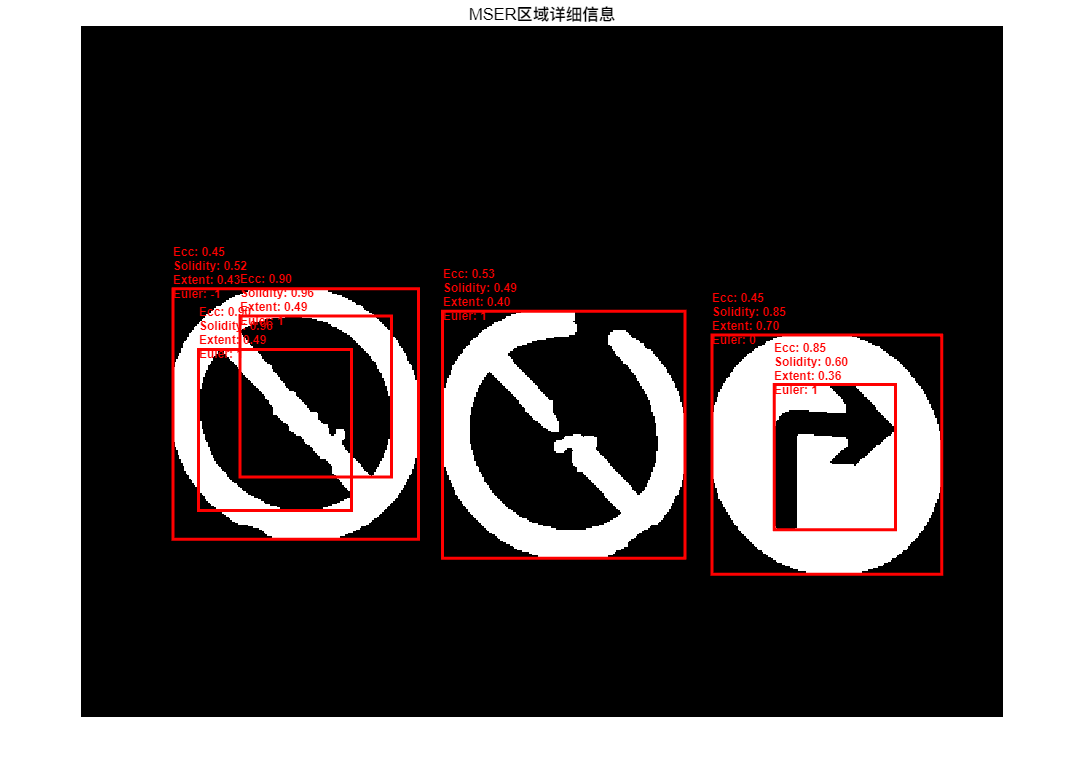

% 提取所有区域的边界框
bboxes = vertcat(mserStats.BoundingBox);

% 创建一个与原始二值图像相同大小的空白图像
binary_dilate = false(size(binary_cleaned));

% 对每个MSER区域进行开操作
for k = 1:length(mserStats)
    % 获取当前区域的边界框
    bbox = round(bboxes(k, :));  % 四舍五入为整数，以确保框的坐标在图像范围内

    % 获取当前区域的二值图像
    subImage = imcrop(binary_cleaned, bbox);

    % 使用膨胀运算进行处理
    opened_subImage = imdilate(subImage, strel('square', 5));

    % % 显示效果
    % figure
    % subplot(1,2,1)
    % imshow(subImage)
    % subplot(1,2,2)
    % imshow(opened_subImage)

    % 确保 opened_subImage 与 bbox 区域大小一致
    [h, w] = size(opened_subImage);
    binary_dilate(bbox(2):bbox(2)+h-1, bbox(1):bbox(1)+w-1) = opened_subImage;
end
getMSERDetail(binary_dilate)

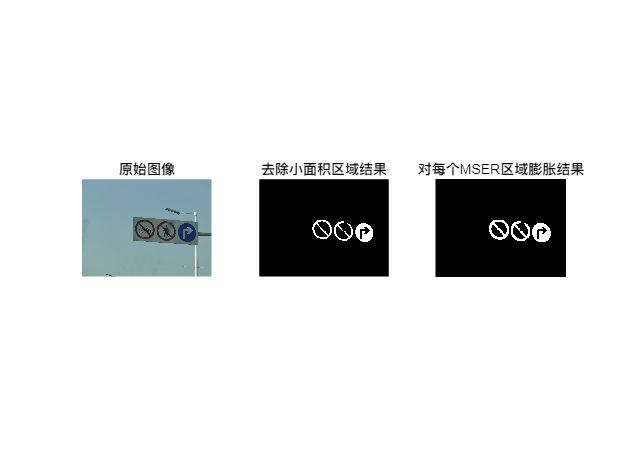

figure
subplot(1,3,1)
imshow(img)
title('原始图像');
subplot(1,3,2)
imshow(binary_cleaned)
title('去除小面积区域结果');
subplot(1,3,3)
imshow(binary_dilate)
title('对每个MSER区域膨胀结果');

### 5.4 对区域过滤&合并重叠目标框

% 对区域膨胀后的图像再次检测MSER区域
[mserRegions, mserConnComp] = detectMSERFeatures(binary_dilate, ...
    'RegionAreaRange', [30 150000], ...
    'ThresholdDelta', 5.5);
% 使用 regionprops 测量 MSER 区域的属性
mserStats = regionprops(mserConnComp, 'BoundingBox', 'Area','Eccentricity', ...
    'Solidity', 'Extent', 'Euler', 'Image');

% 获取所有区域的边界框
bboxes = vertcat(mserStats.BoundingBox);

if ~isempty(bboxes)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 对MSER区域的各项属性进行筛选 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 参数
    % Eccentricity >= 0.85
    % Solidity < 0.3
    % Extent < 0.2
    % Area < 250
    % 特别注意: 不满足上述条件的区域需要进一步进行判断是否包含在一个较大区域，若是 保留；否 删除

    % 计算宽高比例和其他属性的筛选条件
    if size(bboxes, 1) > 2
        w = bboxes(:, 3);
        h = bboxes(:, 4);
        filterIdx = (w ./ h)' > 1.2;
        filterIdx = filterIdx | [mserStats.Eccentricity] >= 0.85;
        filterIdx = filterIdx | [mserStats.Solidity] < 0.3;
        filterIdx = filterIdx | [mserStats.Extent] < 0.2 ;%| [mserStats.Extent] > 0.9;
        % filterIdx = filterIdx | [mserStats.EulerNumber] < -4;
        filterIdx = filterIdx | [mserStats.Area] < 250;

        % 检查每个小区域是否包含在较大区域内的重叠比例
        for i = 1:length(mserStats)
            if filterIdx(i)
                smallBox = bboxes(i, :);
                for j = 1:length(mserStats)
                    if ~filterIdx(j) && i ~= j
                        largeBox = bboxes(j, :);
                        overlapArea = rectint(smallBox, largeBox);
                        smallBoxArea = smallBox(3) * smallBox(4);
                        overlapRatio = overlapArea / smallBoxArea;
                        if overlapRatio > 0.75
                            filterIdx(i) = false;
                            break;
                        end
                    end
                end
            end
        end

        % 移除不符合条件的区域
        mserStats(filterIdx) = [];
        mserRegions(filterIdx) = [];
        bboxes(filterIdx, :) = [];
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 调整边界框的大小并确保在图像边界内 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    xmin = bboxes(:, 1);
    ymin = bboxes(:, 2);
    xmax = xmin + bboxes(:, 3) - 1;
    ymax = ymin + bboxes(:, 4) - 1;

    expansionAmount = 0;
    xmin = (1 - expansionAmount) * xmin;
    ymin = (1 - expansionAmount) * ymin;
    xmax = (1 + expansionAmount) * xmax;
    ymax = (1 + expansionAmount) * ymax;

    xmin = max(xmin, 1);
    ymin = max(ymin, 2);
    xmax = min(xmax, size(binary_dilate, 2));
    ymax = min(ymax, size(binary_dilate, 1));

    expandedBBoxes = [xmin ymin xmax - xmin + 1 ymax - ymin + 1];

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 合并重复检测框（可以理解为yolo的NMS） %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 计算边界框之间的重叠率
    overlapRatio = bboxOverlapRatio(expandedBBoxes, expandedBBoxes);

    % 将边界框与自身的重叠率设置为零，简化图形表示
    n = size(overlapRatio, 1);
    overlapRatio(1:n+1:n^2) = 0;

    % 创建图并查找连接的区域
    g = graph(overlapRatio);
    componentIndices = conncomp(g);

    % 基于最小和最大尺寸合并边界框
    xmin = accumarray(componentIndices', xmin, [], @min);
    ymin = accumarray(componentIndices', ymin, [], @min);
    xmax = accumarray(componentIndices', xmax, [], @max);
    ymax = accumarray(componentIndices', ymax, [], @max);

    textBBoxes = [xmin ymin xmax - xmin + 1 ymax - ymin + 1];

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 对可能为交通标识的区域进行进一步的检测 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 1. 若一个可能的交通标识的区域是由两个以上MSER区域合并而来的（一个大框里边有一个以上小框），则标记为交通标识区域
    % 2. 若一个可能的交通标识的区域是由仅一个MSER区域标注，
    %    检查这个可能的交通标识的区域水平或垂直方向是否有已经标记为交通标识的区域，有则标记为交通标识区域
    %    原理为：交通标识一般都在一根杆上，不是水平一条直线就是垂直一条直线

    % 设置误差范围为边界框尺寸的10%
    errorMargin = 0.20;

    % 找到只包含一个区域的边界框的索引
    numRegionsInGroup = histcounts(componentIndices);
    singleRegionIdx = find(numRegionsInGroup == 1);
    flag = true(size(numRegionsInGroup));
    flag(singleRegionIdx) = false;

    % 对于每个只包含一个区域的边界框
    for idx = 1:length(singleRegionIdx)
        if length(numRegionsInGroup) <= 2
            flag(:)=true;
            break
        end

        % 获取当前边界框的位置信息
        currentBox = textBBoxes(singleRegionIdx(idx), :);
        xmin1 = currentBox(1);
        ymin1 = currentBox(2);
        xmax1 = xmin1 + currentBox(3);
        ymax1 = ymin1 + currentBox(4);

        % 寻找与当前边界框位置处于同一直线上的其他边界框
        for j = 1:size(textBBoxes, 1)
            if j ~= singleRegionIdx(idx)
                % 获取比较的边界框的位置信息
                compareBox = textBBoxes(j, :);
                xmin2 = compareBox(1);
                ymin2 = compareBox(2);
                xmax2 = xmin2 + compareBox(3);
                ymax2 = ymin2 + compareBox(4);

                % 判断是否处于同一直线上（水平或垂直方向），且误差在10%范围内
                if ((abs(ymin1 - ymin2) <= errorMargin * currentBox(4) && abs(ymax1 - ymax2) <= errorMargin * currentBox(4)) || ...
                        (abs(xmin1 - xmin2) <= errorMargin * currentBox(3) && abs(xmax1 - xmax2) <= errorMargin * currentBox(3))) && ...
                        numRegionsInGroup(j) >= 2
                    % 如果是同一直线上的区域，设置标志变量为 true
                    flag(singleRegionIdx(idx)) = true;
                    break;  % 跳出内层循环
                end
            end
        end
    end

    % 标记为交通标识的区域
    textBBoxes_new = textBBoxes(flag,:);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 最后一次对标记为交通标识的区域进行长宽比的校验 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 计算符合条件的边界框
    mod_bb = [];
    scale = 1.5;% 长/宽 宽/长
    for image_index = 1:size(textBBoxes_new, 1)
        in_box = textBBoxes_new(image_index, :);
        height = in_box(1, 4);
        width = in_box(1, 3);

        if ~(height / width > scale || width / height > scale)
            mod_bb = [mod_bb; in_box];
        end
    end
end

% 交通标志区域坐标
mod_bb

mod_bb =   759.5000  347.5000  144.0000  150.0000
  421.5000  318.5000  154.0000  157.0000
  590.5000  332.5000  152.0000  155.0000


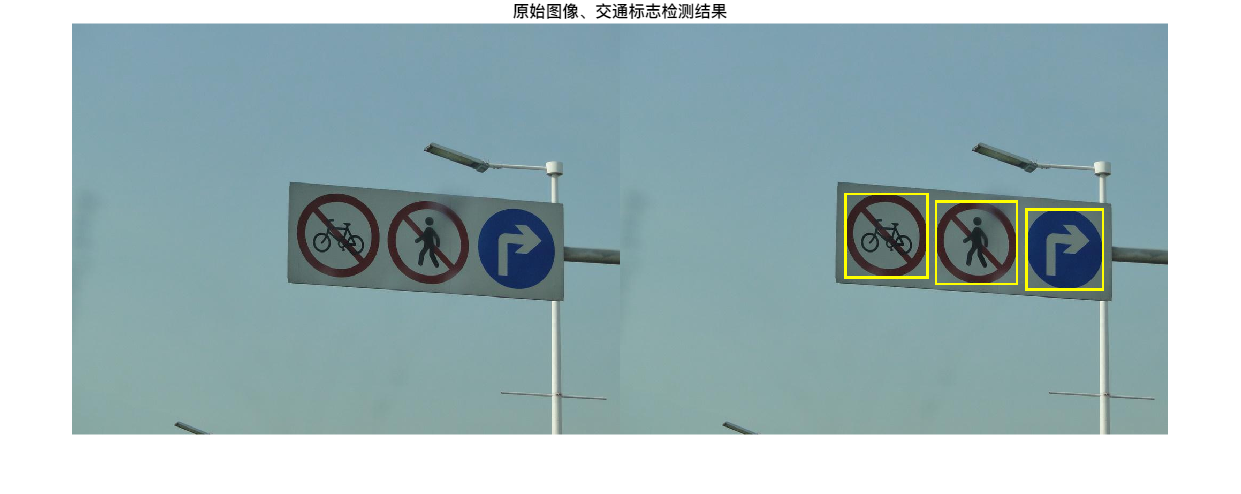


% 在图上标记
sign_Result = insertShape(img, 'Rectangle', textBBoxes_new, 'LineWidth', 5);
figure
imshow([img, sign_Result]);
title('原始图像、交通标志检测结果');

## 6 最终结果

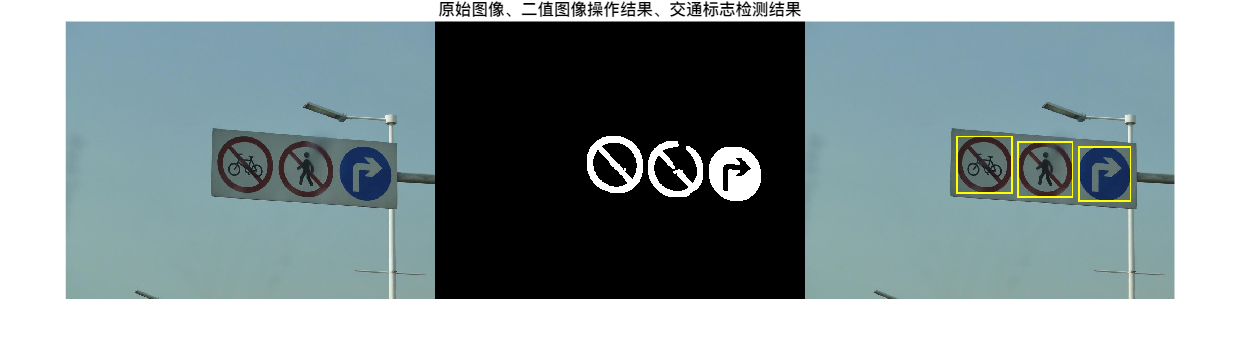

figure

imshow([img, ...
    255*cat(3, binary_dilate, binary_dilate, binary_dilate), ...
    sign_Result]);
title('原始图像、二值图像操作结果、交通标志检测结果');

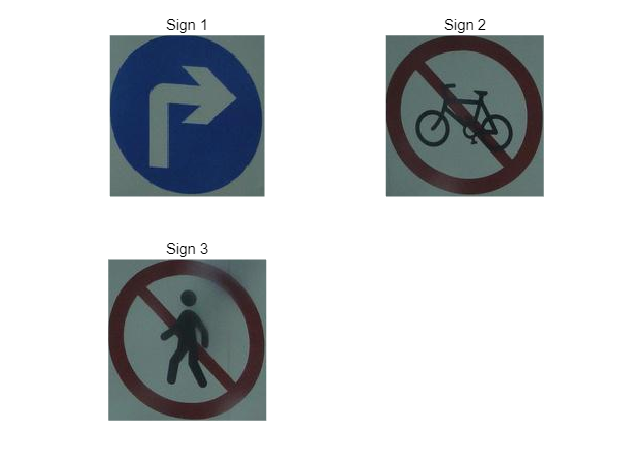


% 存储裁剪出来的图像
signs = {};

% 检查 mod_bb 是否为空
if ~isempty(mod_bb)
    % 循环遍历每个边界框
    for i = 1:size(mod_bb, 1)
        % 获取当前边界框的坐标和尺寸
        bbox = mod_bb(i, :);

        % 裁剪图像
        croppedImage = imcrop(img, bbox);

        % 将裁剪后的图像添加到 cell 数组中
        signs{end + 1} = croppedImage;
    end
end

% 显示裁剪后的结果
figure;
for i = 1:length(signs)
    subplot(ceil(sqrt(length(signs))), ceil(sqrt(length(signs))), i);
    imshow(signs{i});
    title(sprintf('Sign %d', i));
end

## 7 封装函数

[mod_bb,signs] = Detection(img,85);

mod_bb

mod_bb =   759.5000  347.5000  144.0000  150.0000
  421.5000  318.5000  154.0000  157.0000
  590.5000  332.5000  152.0000  155.0000


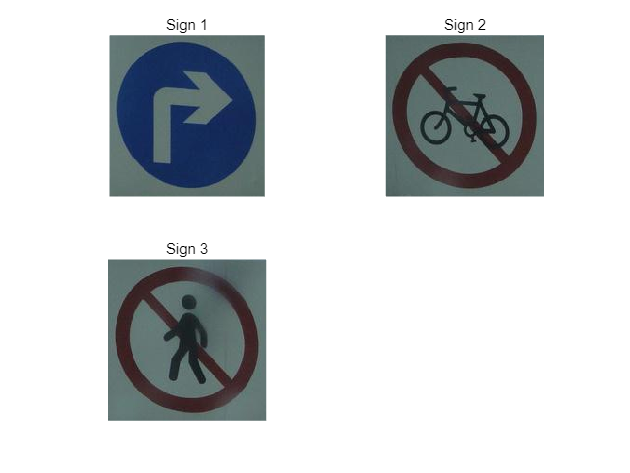


% 显示裁剪后的结果
figure;
for i = 1:length(signs)
    subplot(ceil(sqrt(length(signs))), ceil(sqrt(length(signs))), i);
    imshow(signs{i});
    title(sprintf('Sign %d', i));
end